# Centering and Scaling

Instructions are in the task pane to the left. Complete and submit each task one at a time. This code sets up the activity.

yr = 2000:2007

yr =         2000        2001        2002        2003        2004        2005        2006        2007


penguins = [5.49  7.03  7.73  7.70  9.29  9.21  11.89  10.85]

penguins =     5.4900    7.0300    7.7300    7.7000    9.2900    9.2100   11.8900   10.8500


## Task 1

When performing polynomial fitting with large *x* values, numerical precision limitations can lead to inaccurate results. The `polyfit` function will give a warning in this case.

**TASK1**

Use `polyfit` to fit a third degree polynomial to the vector `penguins` as a function of `yr`. Store the resulting coefficients in a vector named `c`.

**Hint1**

The first two inputs to `polyfit` are `x` and `y` respectively. The third input is the degree of the polynomial.

c = polyfit(yr,penguins,3)

c = 	1.0e+07 *

   -0.0000    0.0000   -0.0058    3.8728


## Task 2

You can avoid the numerical precision limitations by centering and scaling the *x* data when using `polyfit` and `polyval`. To do this, ask for a third output from `polyfit`:

`[``c``,~,``sc``]` `=` `polyfit``(``x``,``y``,``deg``)`

The symbol `~` skips the second output of `polyfit`.

**TASK2**

Use centering and scaling to fit a third degree polynomial to the vector `penguins` as a function of `yr`. Store the polynomial coefficients in a vector named `c` and the scaling information in a variable called `sc`.

**Hint2**

Use the `polyval` function with three outputs. Because you do not need the second output, you can use the `~` placeholder.

`[``c``,~,``sc``]` `=` `polyfit``(``x``,``y``,``deg``)`

[c,~,sc] = polyfit(yr,penguins,3)

c =    -0.0709   -0.0882    2.0878    8.7259


sc = 	1.0e+03 *

    2.0035
    0.0024


## Task 3

When evaluating the polynomial, pass the vector of scaling coefficients `sc` to `polyval` as a fourth input:

`yFit` `=` `polyval``(``c``,``xFit``,``[]``,``sc``)`

**TASK3**

Use `polyval` to evaluate the fitted polynomial at each of the `yr` values. Store the result in `penguinFit`.

**Hint3**

Use `polyval` with four inputs: `c` as the first input, `yr` as the second input, and `sc` as the fourth input. Because you do not need to specify the third input, you can use an empty array, `[]`, as a placeholder.

penguinFit=polyval(c,yr,[],sc)

penguinFit =     5.7694    6.5785    7.4306    8.2967    9.1478    9.9551   10.6896   11.3223


## Further Practice

How does the model look? Plot the data (`penguins` as a function of `yr`) as points, then overlay a plot of the model (`penguinFit`).

Note that you have ignoring some inputs and outputs for `polyfit` and `polyval`. These provide statistical information about the fit, allowing you to do more sophisticated analysis. For example, you can obtain standard error estimates of the predicted fit values.

`[``c``,``S``,``sc``]` `=` `polyfit``(``yr``,``penguins``,``3``)`

`[``penguinFit``,``serr``]` `=` `polyval``(``c``,``yr``,``S``,``sc``)`

With these, you can calculate a 95% prediction interval.

`predInt` `=` `penguinFit` `+` `2``*``[``1``;``-1``]``*``serr`

`plot``(``yr``,``penguins``,``"o"``,``...`

    `yr``,``penguinFit``,``yr``,``predInt``,``"r--"``)`

plot(yr,penguins)
hold on
plot(yr,penguinFit)
legend

[c,S,sc] = polyfit(yr,penguins,3)

c =    -0.0709   -0.0882    2.0878    8.7259


S = struct with fields:
        R: [4×4 double]
       df: 4
    normr: 1.7225


sc = 	1.0e+03 *

    2.0035
    0.0024


[penguinFit,serr] = polyval(c,yr,S,sc)

penguinFit =     5.7694    6.5785    7.4306    8.2967    9.1478    9.9551   10.6896   11.3223


serr =     1.1853    1.0097    1.0255    0.9872    0.9872    1.0255    1.0097    1.1853



predInt = penguinFit + 2*[1;-1]*serr

predInt =     8.1399    8.5980    9.4816   10.2711   11.1222   12.0061   12.7090   13.6928
    3.3989    4.5591    5.3796    6.3223    7.1734    7.9041    8.6701    8.9517


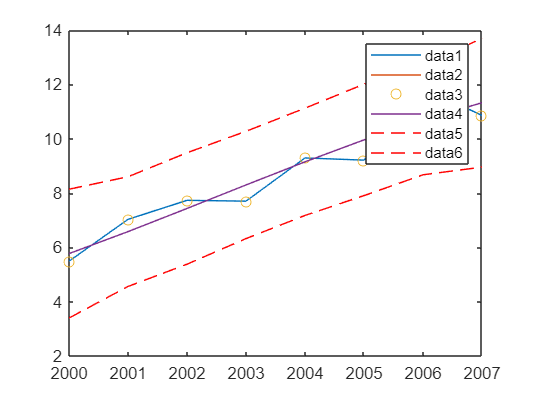

plot(yr,penguins,"o",...
    yr,penguinFit,yr,predInt,"r--")